# Experiment 4.1

## Name: Emily

## Objectives

To evaluate the effect of pole and zero location upon the time response of first- and second-order systems.

### Minimum Required Software Packages

MATLAB, Simulink, and the Control System Toolbox.

## Prelab

### Problem 1

Given the transfer function $G(s) = \frac{a}{s+a}$, evaluate settling time and rise time for the following values of $a$: 1,2,3,4. Also, plot the poles.

**Answer:**

**a = 1**

settling time = 4 seconds,          rise time = 2.2 seconds

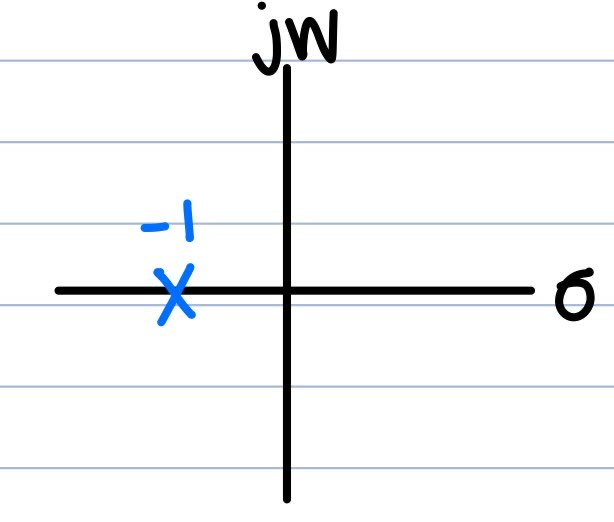

**a = 2**

settling time = 2 seconds,          rise time = 1.1 seconds

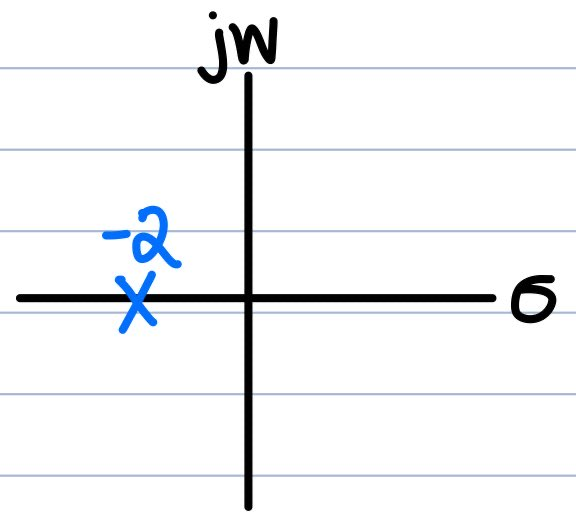

**a = 3**

settling time = 1.33 seconds,     rise time = 0.73 seconds

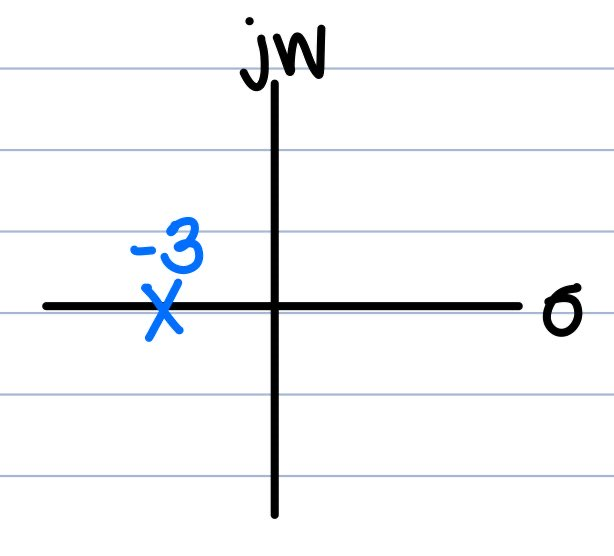

**a = 4**

settling time = 1,                        rise time = 0.55 seconds

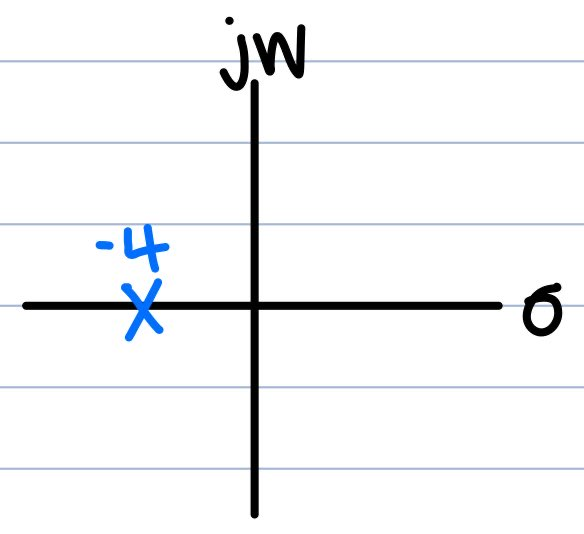

### Problem 2

Given the transfer function $G(s)=\frac{b}{s^2 + as + b}$.

#### 2.a

Evaluate precent overshoot, settling time, peak time, and rise time for the following values: $a=4$, $b=25$. Also, plot the poles. 

**Answer:**

percent overshoot = 25.38%

settling time = 2 seconds

peak time = 0.686 seconds

rise time = 0.2926 seconds

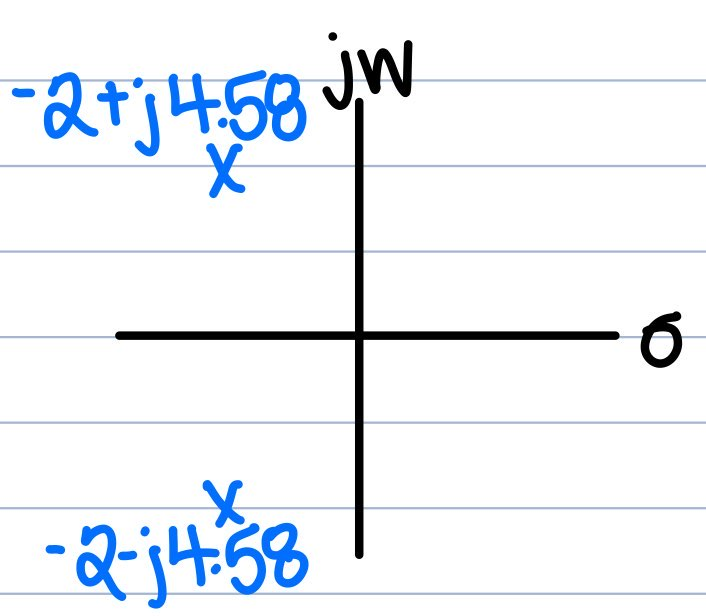

#### 2.b

Calculate the values of $a$ and $b$ so that the imaginary part of the poles remains the same but the real part is increased two times over that of Prelab 2a, and repeat Prelab 2a.

**Answer:**

#### 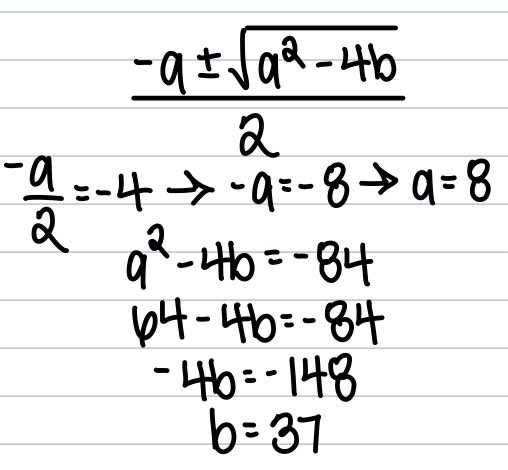

#### **a = 8, b = 37**

percent overshoot = 6.44%

settling time = 1 second

peak time = 0.686 seconds

rise time = 0.331 seconds

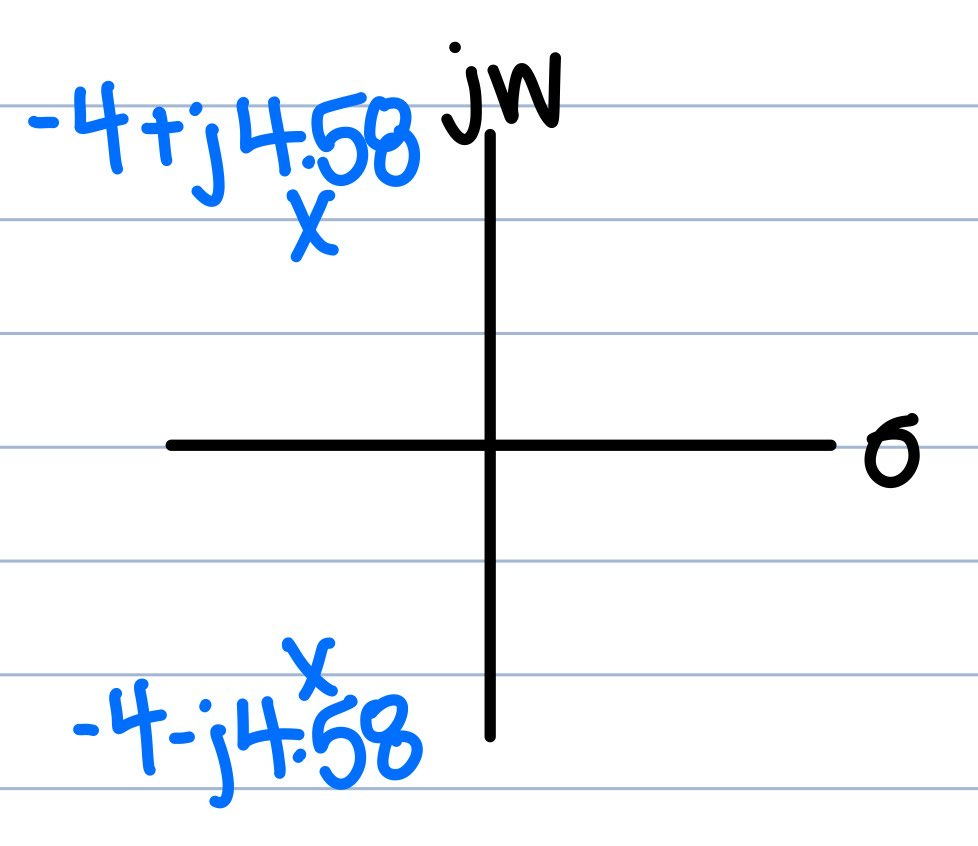

#### 2.c

Calculate the values of $a$ and $b$ so that the imaginary part of the poles remains the same but the real part is decreased by one half over that of Prelab 2a, and repeat Prelab 2a.

**Answer:**

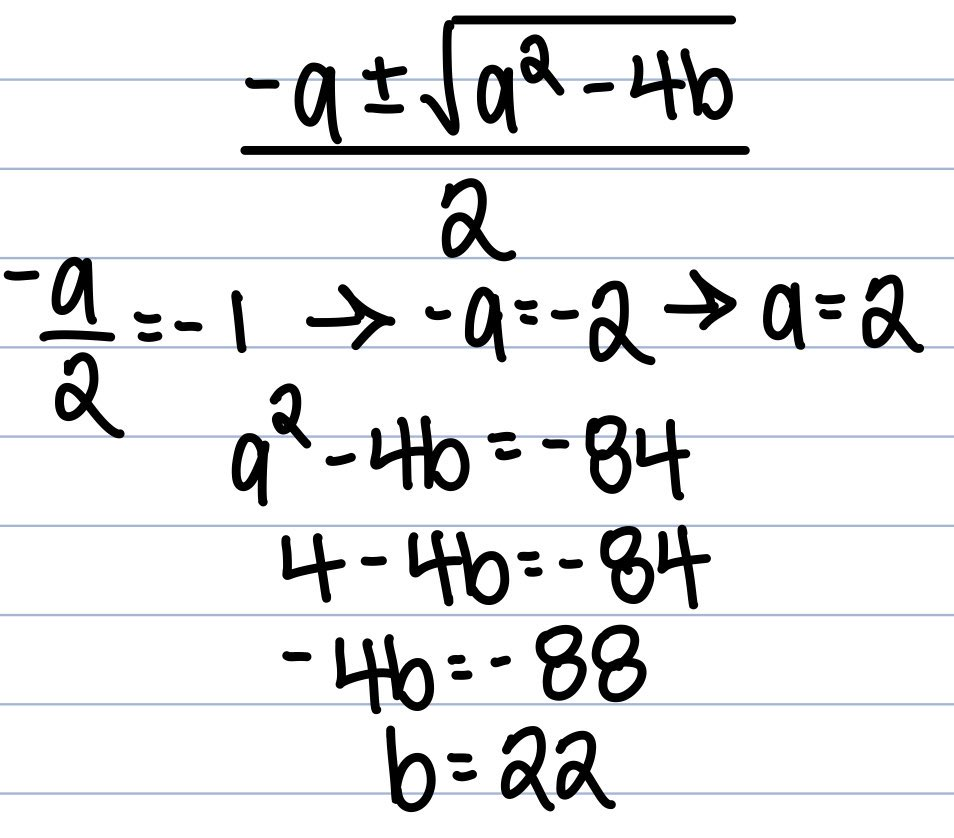

#### **a = 2, b = 22**

percent overshoot = 50.42%

settling time = 4 seconds

peak time = 0.686 seconds

rise time = 0.26 seconds

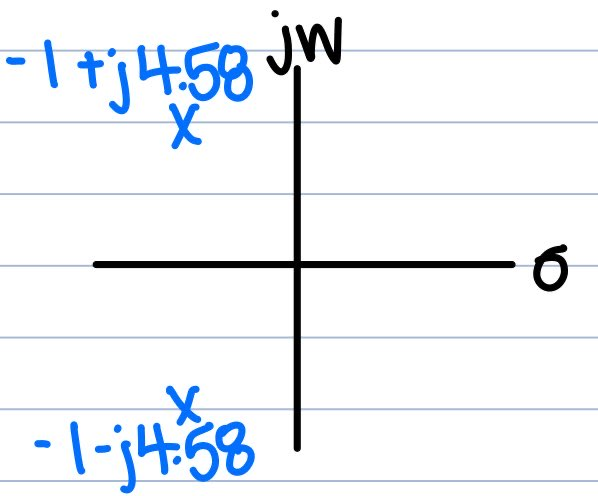

### Problem 3

#### 3.a

For the system of Prelab 2a, calculate the values of $a$ and $b$ so that the real part of the poles remains the same but the imaginary part is increased two times over that of Prelab 2a, and repeat Prelab 2a.  

**Answer:**

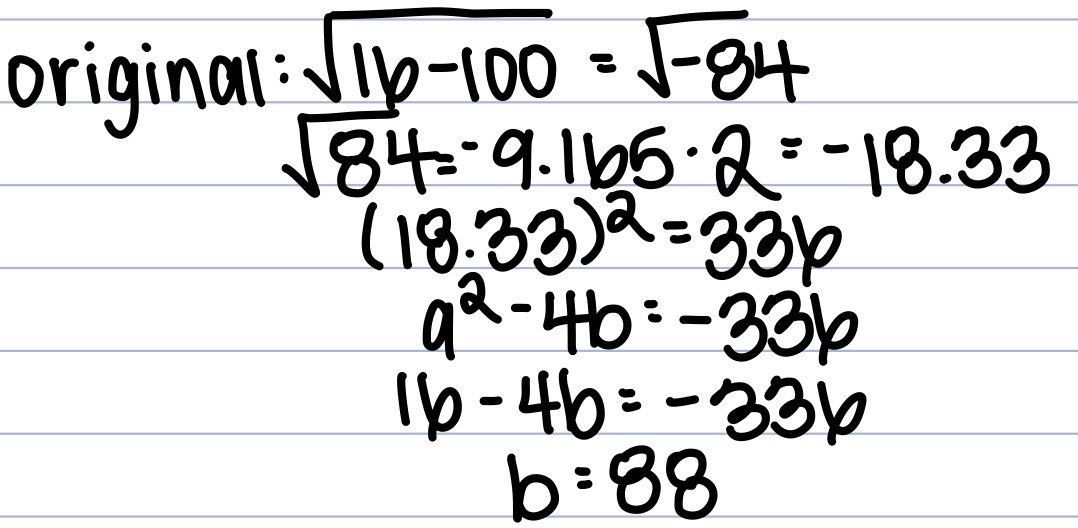

**a = 4, b = 88**

percent overshoot = 50.42%

settling time = 2 seconds

peak time = 0.343 seconds

rise time = 0.13 seconds

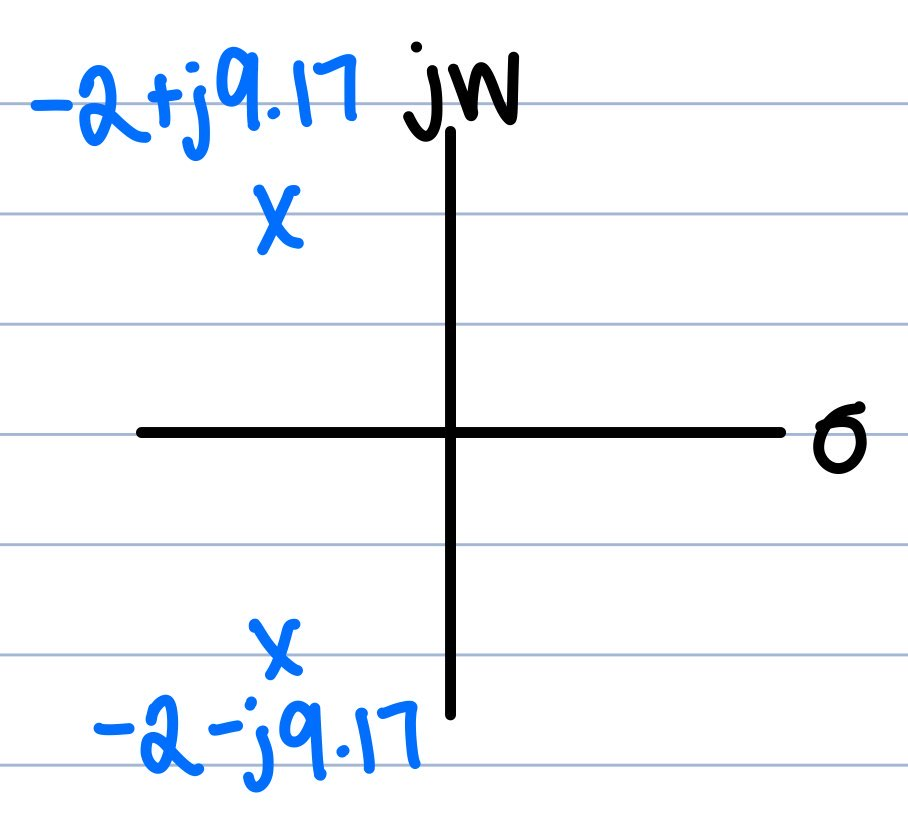

#### 3.b

For the system of Prelab 2a, calculate the values of $a$ and $b$ so that the real part of the poles remains the same but the imaginary part is increased four times over that of Prelab 2a, and repeat Prelab 2a.  

**Answer:**

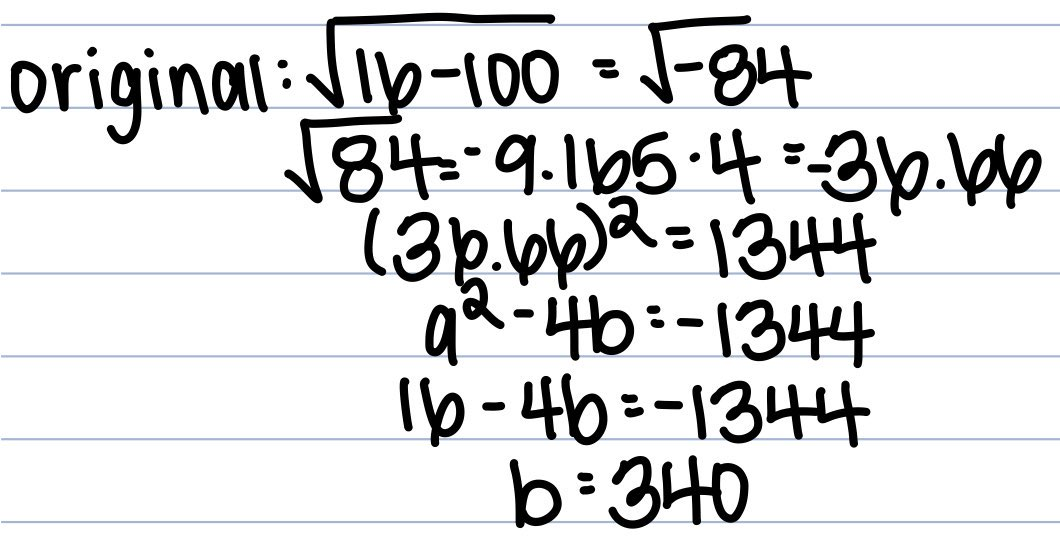

**a = 4, b = 340**

percent overshoot = 71.09%

settling time = 2 seconds

peak time = 0.17 seconds

rise time = 0.06 seconds

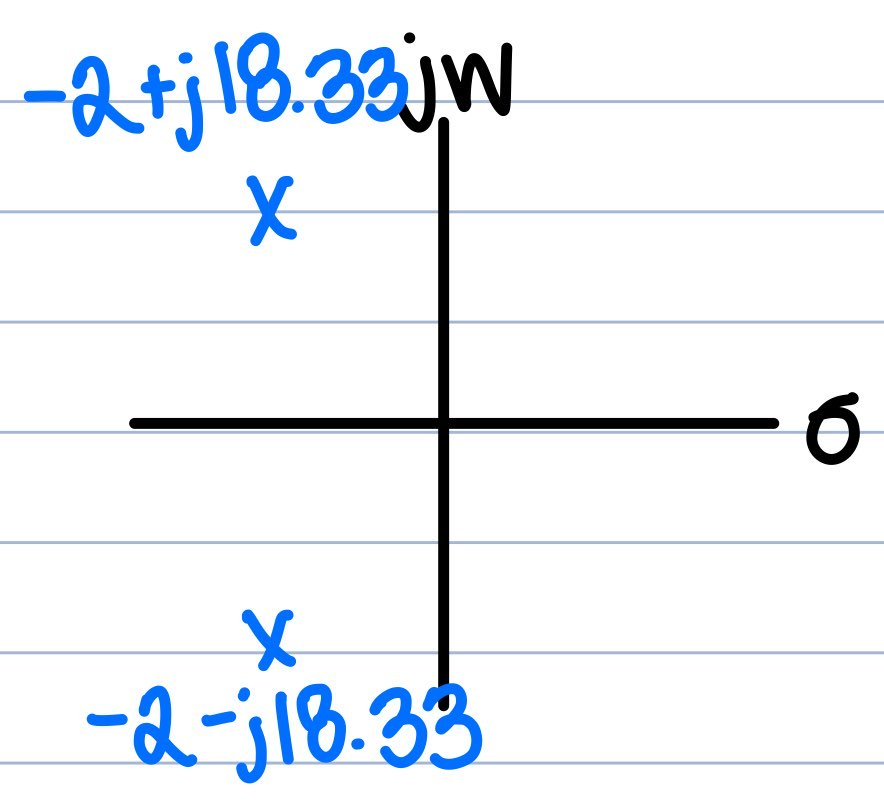

### Problem 4

#### 4.a

For the system of Prelab 2a, calculate the values of *a *and *b *so that the damping ratio remains the same but the natural frequency is increased two times over that of Prelab 2a, and repeat Prelab 2a.  

**Answer:**

**a = 8, b = 100**

percent overshoot = 25.38%

settling time = 1 second

peak time = 0.34 seconds

rise time = 0.15 seconds

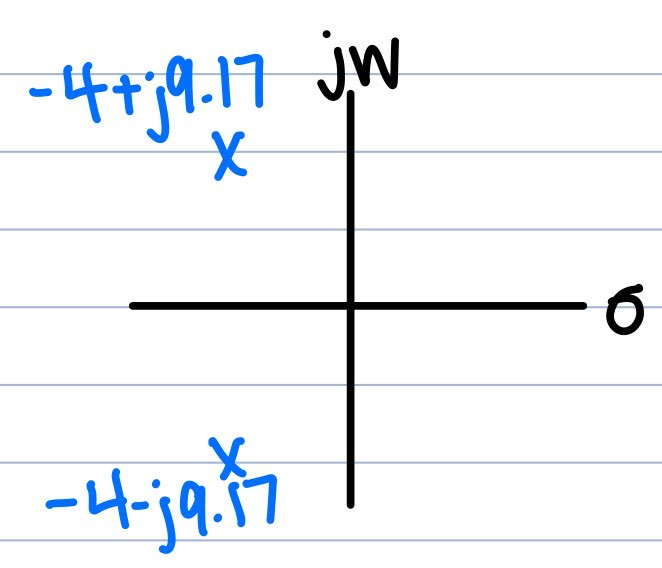

#### 4.b

For the system of Prelab 2a, calculate the values of *a *and *b *so that the damping ratio remains the same but the natural frequency is increased four times over that of Prelab 2a, and repeat Prelab 2a.  

**Answer:**

**a = 16, b = 400**

percent overshoot = 25.38%

settling time = 0.5 seconds

peak time = 0.17 seconds

rise time = 0.07 seconds

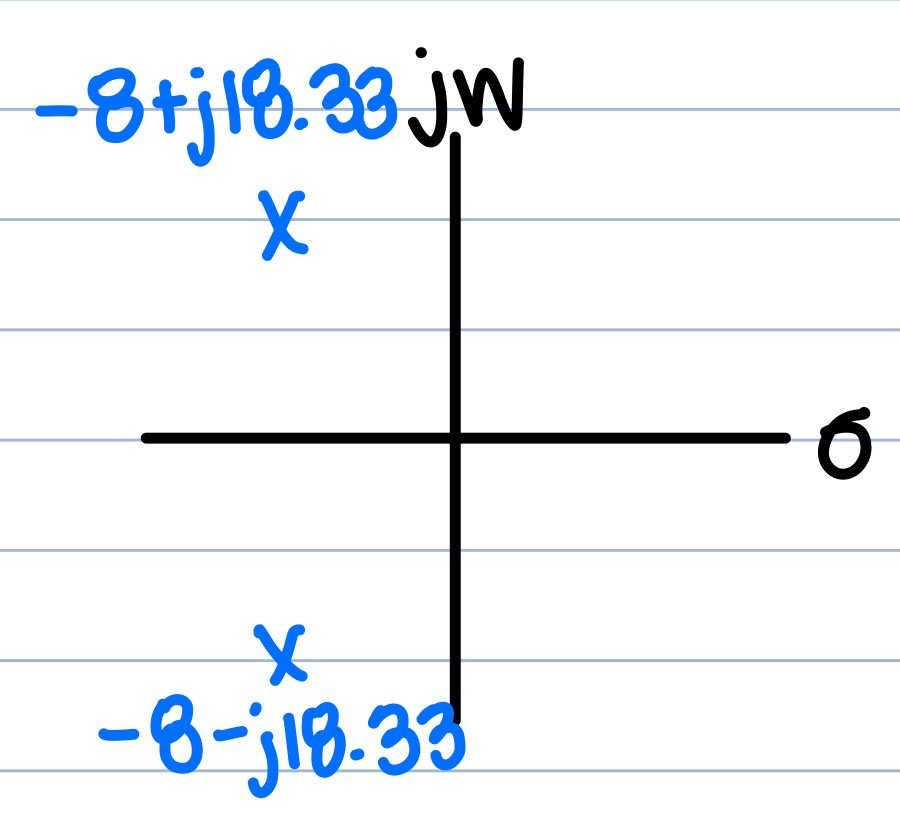

### Problem 5

Briefly describe the effects on the time response as the poles are changed in each of the Prelabs 2, 3, and 4.

**Answer:**

**Prelab 2**

- When the real part of the pole is doubled, percent overshoot decreases, the settling time decreases, the peak time stays the same, and the rise time increases a little bit when compared to Prelab 2a.

- When the real part of the pole is cut in half, percent overshoot increases, the settling time increases, the peak time stays the same, and the rise time decreases a little bit when compared to Prelab 2a.

- When the real part of the pole is cut in half, its percent overshoot and settling time is greater than when the real part is doubled, but its rise time is shorter.

**Prelab 3**

- When the imaginary part of the pole is doubled, the percent overshoot increases, the settling time stays the same, the peak time decreases, and the rise time decreases when compared to Prelab 2a.

- When the imaginary part of the pole is increased four times over, the percent overshoot increases, the settling time stays the same, the peak time decreases, and the rise time decreases when compared to Prelab 2a.

- When the imaginary part of the pole is increased four times over, its percent overshoot is greater than when the imaginary part is doubled, but its peak and rise times are smaller than when the imaginary part is doubled.

**Prelab 4**

- When the natural frequency is doubled, the percent overshoot stays the same, the settling time decreases, the peak time decreases, and the rise time decreases when compared to Prelab 2a.

- When the natural frequency is increased four times over, the percent overshoot stays the same, the settling time decreases, the peak time decreases, and the rise time decreases when compared to Prelab 2a.

- When the natural frequency is increased four times over, its settling, peak, and rise times are all less than when the natural frequency is doubled.

## Lab

### Problem 1

Using Simulink, set up the systems of Prelab 1 and plot the step response of each of the four transfer functions on a single graph by using the Simulink LTI Viewer (See Appendix E.6 online for tutorial). Also, record the values of settling time and rise time for each step response. 

*For your Simulink, please provide a screenshot that **clearly** shows the system.*

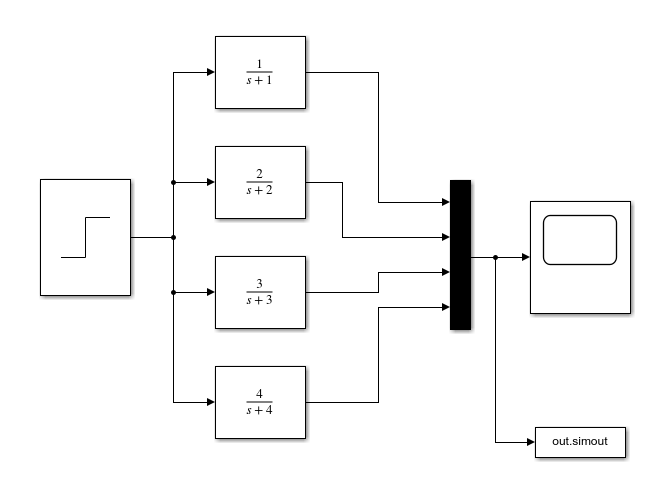

% Settling Times are off by 1 second because the step starts at t=1
figure(1)
hold on
for i = 1; 4
    sim('Lab3Prob1.slx');
    normData = out.simout.Data./out.simout.Data(length(out.simout.Data));
    plot(out.simout.Time, normData, "linewidth", 2);
    stepinfo(out.simout.Data, out.simout.Time)
end

ans = 4

ans = 4×1 struct array with fields:
    RiseTime
    SettlingTime
    SettlingMin
    SettlingMax
    Overshoot
    Undershoot
    Peak
    PeakTime


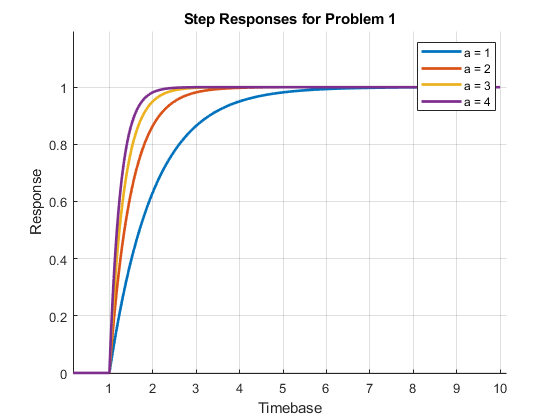

hold off
title("Step Responses for Problem 1")
xlabel("Timebase")
ylabel("Response")
legend(["a = 1" "a = 2" "a = 3" "a = 4"])
grid on

### Problem 2

Using Simulink, set up the systems of Prelab 2. Using the Simulink LTI Viewer, plot the step response of each of the three transfer functions on a single graph. Also, record the values of pervent overshoot, settling time, peak time, and rise time for each step response.

*For your Simulink, please provide a screenshot that **clearly** shows the system.*

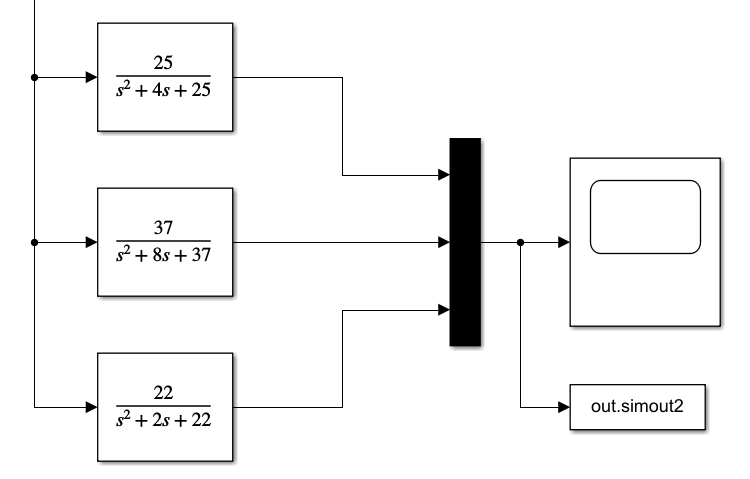

% Settling Times are off by 1 second because the step starts at t=1
figure(2)
hold on
for i = 1; 3
    sim('Lab3Prob1.slx');
    normData = out.simout2.Data./out.simout2.Data(length(out.simout2.Data));
    plot(out.simout2.Time, normData, "linewidth", 2);
    stepinfo(out.simout2.Data, out.simout2.Time)
end

ans = 3

ans = 3×1 struct array with fields:
    RiseTime
    SettlingTime
    SettlingMin
    SettlingMax
    Overshoot
    Undershoot
    Peak
    PeakTime


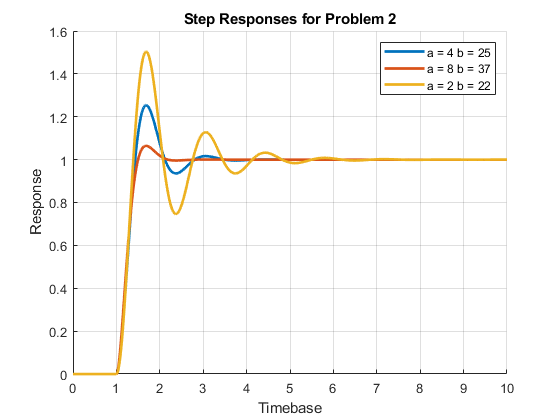

hold off
title("Step Responses for Problem 2")
xlabel("Timebase")
ylabel("Response")
legend(["a = 4 b = 25" "a = 8 b = 37" "a = 2 b = 22"])
grid on

### Problem 3

Using Simulink, set up the systems of Prelab 2a and Prelab 3. Using the Simulink LTI Viewer, plot the step response of each of the three transfer functions on a single graph. Also, record the values of percent overshoot, settling time, peak time, and rise time for each step response.

*For your Simulink, please provide a screenshot that **clearly** shows the system.*

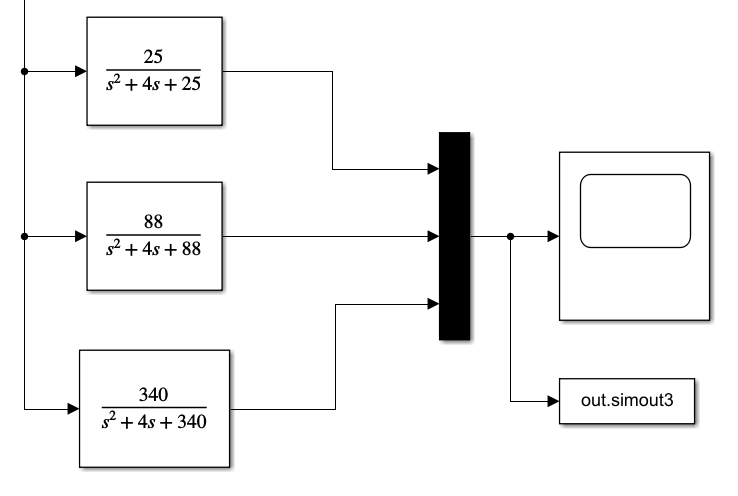

% Settling Times are off by 1 second because the step starts at t=1
figure(3)
hold on
for i = 1; 3
    sim('Lab3Prob1.slx');
    normData = out.simout3.Data./out.simout3.Data(length(out.simout3.Data));
    plot(out.simout3.Time, normData, "linewidth", 2);
    stepinfo(out.simout3.Data, out.simout3.Time)
end

ans = 3

ans = 3×1 struct array with fields:
    RiseTime
    SettlingTime
    SettlingMin
    SettlingMax
    Overshoot
    Undershoot
    Peak
    PeakTime


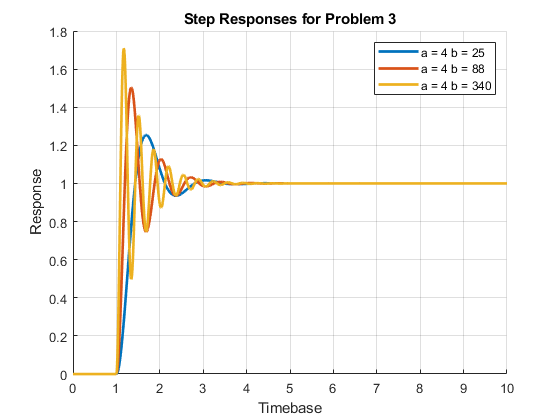

hold off
title("Step Responses for Problem 3")
xlabel("Timebase")
ylabel("Response")
legend(["a = 4 b = 25" "a = 4 b = 88" "a = 4 b = 340"])
grid on

### Problem 4

Using Simulink, set up the systems of Prelab 2a and Prelab 4. Using the Simulink LTI Viewer, plot the step response of each of the three transfer functions on a single graph. Also, record the values of percent overshoot, settling time, peak time, and rise time for each step response.

*For your Simulink, please provide a screenshot that **clearly** shows the system.*

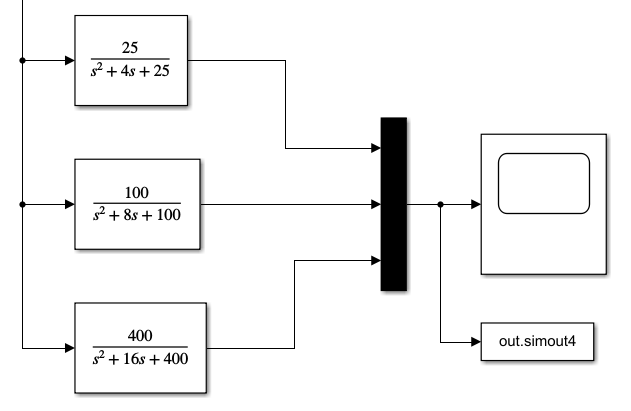

% Settling Times are off by 1 second because the step starts at t=1
figure(4)
hold on
for i = 1; 3
    sim('Lab3Prob1.slx');
    normData = out.simout4.Data./out.simout4.Data(length(out.simout4.Data));
    plot(out.simout4.Time, normData, "linewidth", 2);
    stepinfo(out.simout4.Data, out.simout4.Time)
end

ans = 3

ans = 3×1 struct array with fields:
    RiseTime
    SettlingTime
    SettlingMin
    SettlingMax
    Overshoot
    Undershoot
    Peak
    PeakTime


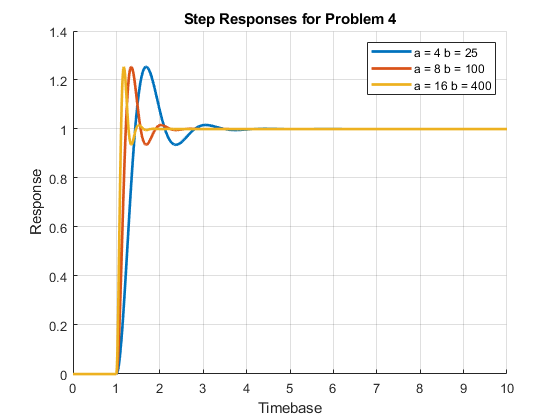

hold off
title("Step Responses for Problem 4")
xlabel("Timebase")
ylabel("Response")
legend(["a = 4 b = 25" "a = 8 b = 100" "a = 16 b = 400"])
grid on

## Postlab

### Problem 1

For the first-order systems, make a table of calculated and experimental values of settling time, rise time, and pole location.

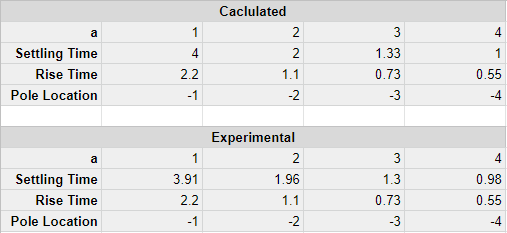

### Problem 2

For the second-order systems of Prelab 2, make a table of caluclated and experimental values of percent overshoot, settling time, peak time, rise time, and pole location.

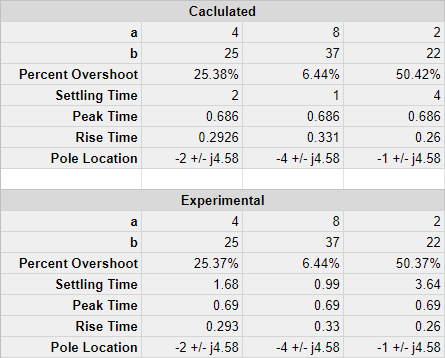

### Problem 3

For the second-order systems of Prelab 2a and Prelab 3, make a table of calculated and experimental values of percent overshoot, settling time, peak time, rise time, and pole location.

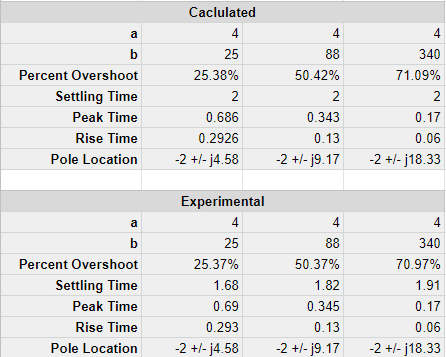

### Problem 4

For the second-order systems of Prelab 2a and Prelab 4, make a table of calculated and experimental values of percent overshoot, settling time, peak time, rise time, and pole location.

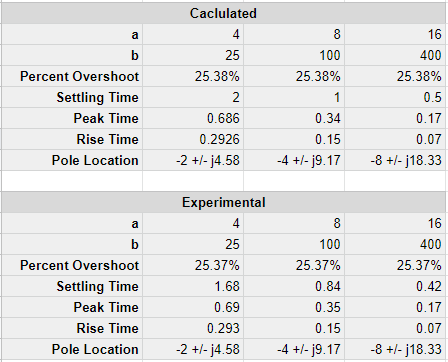

### Problem 5

Discuss the effects of pole location upon the time response for both first- and second-order systems. Discuss any discrepancies between your calculated and experimental values.

**First-Order Systems**

- As the pole location moves further to the left, settling and rise time decrease.

- There was a small difference between the calculated and experimental values for settling time. The calculated and experimental values for rise time were exactly the same.

**Second-Order Systems**

- When the imaginary part of the pole stays the same, but the real part moves further to the left, the percent overshoot decreases, settling time decreases, peak time stays the same, and the rise time increases.

- When the real part of the pole stays the same, but the imaginary part moves further away from the real axis vertically, percent overshoot increases, settling time stays the same, peak time decreases, and rise time decreases.

- When the damping ratio stays the same, but the natural frequency is increased, the percent overshoot stays the same, the settling time decreases, the peak time decreases, and the rise time decreases.

- All calculated and experimental values are basically the same except, for settling time. The calculated value for settling time is always higher than the experimental value for settling time.